# Setup Lowpass Filter Response

w_c = 0.5*pi;
N_1 = 17;
N_2 = 51;
lp_1 = firlp(N_1, w_c);
lp_2 = firlp(N_2, w_c);

## Setup Plotting

set(groot, 'defaultAxesFontSize',15);

## Rectangular Window

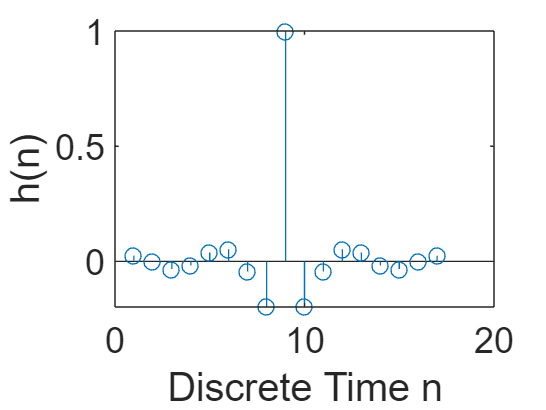

figure;
stem(lp_1);
xlabel("Discrete Time n");
ylabel("h(n)");

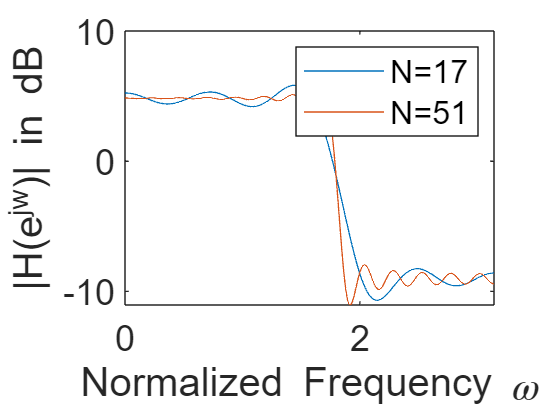


H_rect_1 = fft(lp_1, 100*N_1);
w_1 = linspace(-pi,pi,100*N_1);
H_rect_2 = fft(lp_2, 100*N_2);
w_2 = linspace(-pi,pi,100*N_2);

figure;
plot(w_1, 20*log(abs(H_rect_1)));
hold on;
plot(w_2, 20*log(abs(H_rect_2)));
hold off;
xlim([0,pi]);
xlabel("Normalized Frequency \omega");
ylabel("|H(e^{jw})| in dB");
legend(["N=17","N=51"]);

## Hamming Window

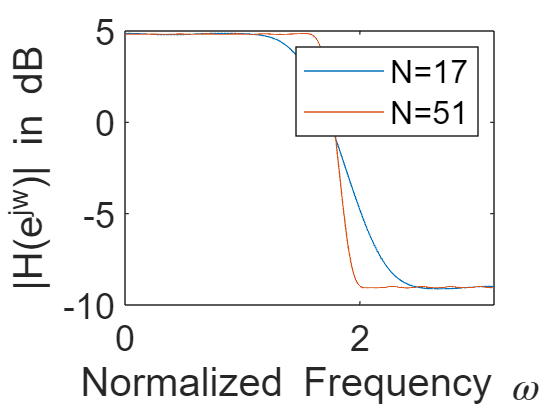

h_1 = hamming(N_1).'.*lp_1;
h_2 = hamming(N_2).'.*lp_2;

H_hamming_1 = fft(h_1, 100*N_1);
w_1 = linspace(-pi,pi,100*N_1);
H_hamming_2 = fft(h_2, 100*N_2);
w_2 = linspace(-pi,pi, 100*N_2);

figure;
plot(w_1, 20*log(abs(H_hamming_1)));
hold on;
plot(w_2, 20*log(abs(H_hamming_2)));
hold off;
xlim([0,pi]);
xlabel("Normalized Frequency \omega");
ylabel("|H(e^{jw})| in dB");
legend(["N=17","N=51"]);

## Bartlett Window

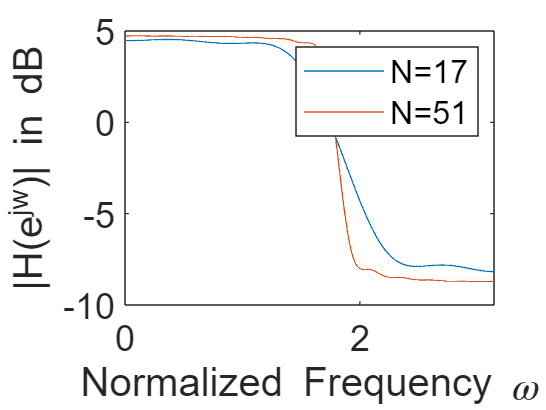

h_1 = bartlett(N_1).'.*lp_1;
h_2 = bartlett(N_2).'.*lp_2;

H_bartlett_1 = fft(h_1, 100*N_1);
w_1 = linspace(-pi,pi,100*N_1);
H_bartlett_2 = fft(h_2, 100*N_2);
w_2 = linspace(-pi,pi, 100*N_2);

figure;
plot(w_1, 20*log(abs(H_bartlett_1)));
hold on;
plot(w_2, 20*log(abs(H_bartlett_2)));
hold off;
xlim([0,pi]);
xlabel("Normalized Frequency \omega");
ylabel("|H(e^{jw})| in dB");
legend(["N=17","N=51"]);